# Phase-lead compensator to explain phase-leading behavior in *Drosophila* head movements

clear; close all; clc
syms s I c k K_p K_d K_i a_2 tau K
assume([I c k s]>=0)
assume([I c k],'real')
freqRange = logspace(-1,2,10000);

## Contol Framework

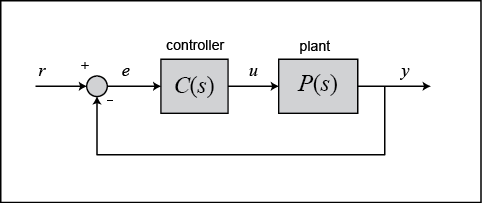

### Plant

Natural Frequency (rad/s)

wn = 50;

Damping Ratio

z = 1.2;

Head inertia about rotation point (kg*m^2)

I = 1;

Head stiffness (N*m/rad)

k = wn^(2)*I;

Head critical damping (N*m*s/rad)

cc = 2*sqrt(k*I);

Head damping (N*m*s/rad)

c = z*cc;
P(s) = 1/(I*s^(2) + c*s + k)

$$P(s) = \frac{1}{s^{2}+120\,s+2500}$$

### Controller to achieve zero steady-state error

C1(s) = K*(1/s)

$$C1(s) = \frac{K}{s}$$

### Closed-Loop Model


$$G\left(s\right)=\frac{Y\left(s\right)}{R\left(s\right)}=\frac{P\left(s\right)C\left(s\right)}{1+P\left(s\right)C\left(s\right)}$$


G(s) = collect(simplify(P(s)*C1(s)/(1 + P(s)*C1(s))),s)

$$G(s) = \frac{K}{s^{3}+120\,s^{2}+2500\,s+K}$$

### Error Dynamics


$$H\left(s\right)=\frac{E\left(s\right)}{R\left(s\right)}=\frac{1}{1+P\left(s\right)C\left(s\right)}$$


H(s) = collect(simplify(expand(1/(1+P(s)*C1(s)))),s)

$$H(s) = \frac{s^{3}+120\,s^{2}+2500\,s}{s^{3}+120\,s^{2}+2500\,s+K}$$

#### For ramp input

$E\left(s\right)=\frac{R\left(s\right)}{1+P\left(s\right)C\left(s\right)}$    where $R\left(s\right)=\frac{1}{s^2 }$

R = 1/s^(2);

#### Steady-State Error using FVT


$$e_{\mathrm{ss}} =\underset{t\to \infty }{\mathrm{lim}} \;e\left(t\right)=\underset{s\to 0}{\mathrm{lim}} \;\mathrm{sE}\left(s\right)$$


Ess = limit(s*H(s)*R,s,0)

$$Ess = \frac{2500}{K}$$

#### Neccesary Gain for steady-state error less than 0.02

K_num = solve(Ess==0.02,K)

$$K\_num = 125000$$

% K_num = 125000

#### The new subcomponents

C1(s) = subs(C1(s),K,K_num)

$$C1(s) = \frac{125000}{s}$$

C1(s) = 1;
G(s) = 1000*simplify(expand(P(s)*C1(s)/(1 + P(s)*C1(s))))

$$G(s) = \frac{125000000}{s^{3}+120\,s^{2}+2500\,s+125000}$$

[MAG{1},PHS{1},FREQ{1}] = bode(sym2tf(G(s)),freqRange);

## Phase-Lead Compensator Controller Design

The controller is of the form


$$C\left(s\right)=\frac{a_2 \tau s+1}{\tau s+1}$$


C2(s) = (a_2*tau*s + 1)/(tau*s + 1)

$$C2(s) = \frac{a_{2}\,s\,\tau +1}{s\,\tau +1}$$

The phase addition and  frequency peak are defined as

$\phi_{\mathrm{max}} ={\mathrm{sin}}^{-1} \left(\frac{a_2 -1}{a_2 +1}\right)$   &   $\omega_{\mathrm{max}} =\frac{1}{\tau \sqrt{a_2 }}$

wm = 0.1;
phi = deg2rad(20);
a2_num = double(solve(phi == asin((a_2-1)/(a_2+1))))

a2_num = 2.0396

tau_num = 1/(wm*sqrt(a2_num))

tau_num = 7.0021

The compensator controller becomes

C2(s) = simplify(expand(subs(C2(s),[a_2 tau],[a2_num tau_num])));

And the combined controller

C(s) = C1(s)*C2(s);

The new closed-loop model

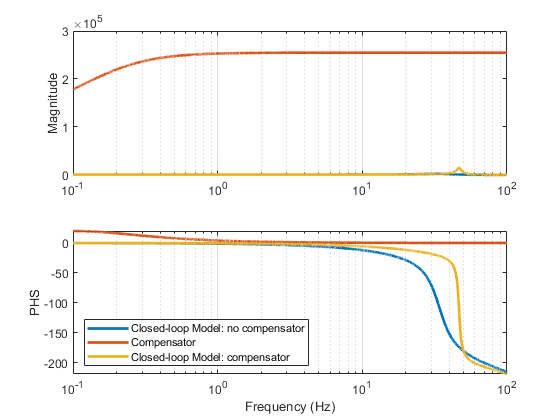

G(s) = 1000*simplify(expand(P(s)*C(s)/(1 + P(s)*C(s))));

[MAG{2},PHS{2},FREQ{2}] = bode(sym2tf(C(s)),freqRange);
[MAG{3},PHS{3},FREQ{3}] = bode(sym2tf(G(s)),freqRange);

figure (1) ; clf
for kk = 1:length(MAG)
    ax(1) = subplot(2,1,1);
    semilogx(FREQ{kk},squeeze(MAG{kk}),'LineWidth',2)
    hold on
    ylabel('Magnitude')
    
    ax(2) = subplot(2,1,2);
    semilogx(FREQ{kk},squeeze(PHS{kk}),'LineWidth',2)
    hold on
    ylabel('PHS')
    xlabel('Frequency (Hz)')
end
set(ax,'XLim',10.^[-1 2],'XGrid','on')
leg = legend('Closed-loop Model: no compensator','Compensator','Closed-loop Model: compensator');
set(leg,'Location','southwest')